# 扩展状态估计器

note5介绍的鲁棒跟踪控制不仅能够使系统的输出跟随参考信号，也能够抑制输入中存在的同类扰动，从控制器结构上来看，note5所述的鲁棒跟踪控制相当于修改了控制律，而不影响状态估计器。换个思路想，能够通过修改状态估计器，使之连同外部扰动一起估计呢？这就要用到扩展状态估计器。

设系统的参考信号$r$满足微分方程$\ddot r+\alpha_1 \dot r + \alpha_0 r=0$，为了抑制同类扰动，设系统受到的扰动折合到输入的信号为$\rho$，则其同样满足微分方程（以二阶为例）$\ddot \rho+\alpha_1 \dot \rho + \alpha_0 \rho=0$。

此时，系统的状态空间表达式为$\[\left\{ {\begin{array}{*{20}{l}}
  {{\mathbf{\dot x}} = {\mathbf{Ax}} + {\mathbf{B}}(u+\rho)} \\ 
  {y = {\mathbf{Cx}} } 
\end{array}} \right.\]$。

如果扩展状态观测器能够对扰动进行估计，那么控制信号就可以写为$u=-\mathbf{K}\hat\mathbf{x} - \hat \rho$。

为了对扰动进行估计，我们选取扩展状态$\mathbf{z} = \left[ \rho \ \dot\rho \ \mathbf{x}^T\right]^T$，则扩展状态的状态空间为$\[\left\{ {\begin{array}{*{20}{l}}
  {{\mathbf{\dot z}} = {{\mathbf{A}}_z}{\mathbf{z}} + {{\mathbf{B}}_z}u} \\ 
  {y = {{\mathbf{C}}_z}{\mathbf{z}}} 
\end{array}} \right.\]$。

其中$\[{{\mathbf{A}}_z} = \left[ {\begin{array}{*{20}{c}}
  0&1&{\mathbf{0}} \\ 
  { - {\alpha _0}}&{ - {\alpha _1}}&{\mathbf{0}} \\ 
  {\mathbf{B}}&{\mathbf{0}}&{\mathbf{A}} 
\end{array}} \right]{\text{  , }}{{\mathbf{B}}_z} = \left[ {\begin{array}{*{20}{c}}
  0 \\ 
  0 \\ 
  {\mathbf{B}} 
\end{array}} \right]{\text{  ,  }}{{\mathbf{C}}_z} = \left[ {\begin{array}{*{20}{c}}
  0&0&{\mathbf{C}} 
\end{array}} \right]\]$。

设计状态估计器为：$\[{\mathbf{\dot \hat z}} = {{\mathbf{A}}_z}{\mathbf{z}} + {{\mathbf{B}}_z}u + {\mathbf{L}}_z\left( {y - {{\mathbf{C}}_z}{\mathbf{z}}} \right)\]$，根据$\[{{\mathbf{A}}_z} - {{\mathbf{L}}_z}{{\mathbf{C}}_z}\]$的特征值进行极点布置即可实现估计器设计，最后结合$u=-\mathbf{K}\hat\mathbf{x} - \hat \rho$完成整个控制器设计。

我们依然以note5中的负弹簧、正弦参考信号$\ddot r + r= 0 \ , ({\alpha _0} =1\ ,\  {\alpha _1} = 0)$为例，控制器增益$\mathbf{K}$已在note3中设计，此处直接引用。

将扩展状态估计器的极点布置在$\[\left[ {\begin{array}{*{20}{c}}
{ - 0.5 \pm 0.866j}&{ - 5}&{ - 6}
\end{array}} \right]\]$。

set(groot,'DefaultLineLineWidth',1.5)
set(groot,'DefaultAxesFontSize',10)
set(groot,'DefaultFigureColor','w')
set(groot,'DefaultAxesFontWeight','bold')
close all
clear;clc

T = 40;
Ts = 1e-3;

% Plant
x0 = [0.3 0.1]';
omgn = 2;
A = [0 1; omgn^2 0];
B = [0 1]';
C = [1 0];

% Control Law
K = [5 1];

% Extended Estimator
alpha0 = 1;
alpha1 = 0;
Az = [0 1 0 0; -alpha0 -alpha1 0 0; B zeros(2,1) A];
Cz = [0 0 C];
Bz = [0;0;B];
p = [-0.5+0.866j -0.5-0.866j -5 -6];
Lz = place(Az',Cz',p);
Lz = Lz';

在被控对象的速度、加速度分别引入同频不同幅度、相位的扰动，而不引入参考信号时，被控对象的输出如下图所示，可见该控制器确实能够抑制扰动。

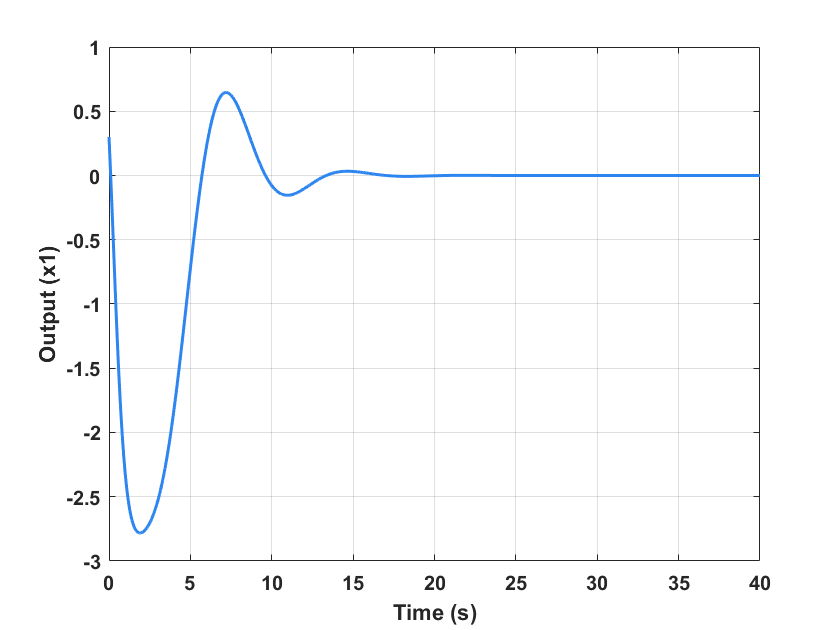

rFlag = 0;
wFlag = 1;
sim('model6_ExtendedEstimator.slx')

figure
plot(t,x(:,1))
grid on
xlabel('Time (s)')
ylabel('Output (x1)')

同时引入扰动和参考信号，此时系统的输出如下图所示，跟踪误差收敛于0。可见该方式能够使系统跟踪参考信号，并抑制同类扰动。

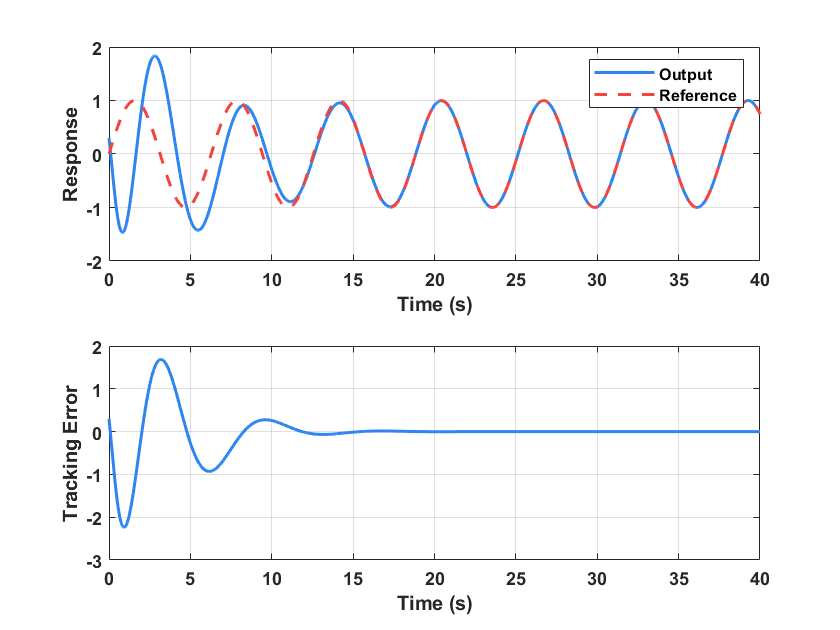

rFlag = 1;
wFlag = 1;
sim('model6_ExtendedEstimator.slx')

figure
subplot(2,1,1)
plot(t,x(:,1))
hold on
grid on
plot(t,r,'--')
legend('Output','Reference')
xlabel('Time (s)')
ylabel('Response')
subplot(2,1,2)
plot(t,x(:,1)-r)
grid on
xlabel('Time (s)')
ylabel('Tracking Error')